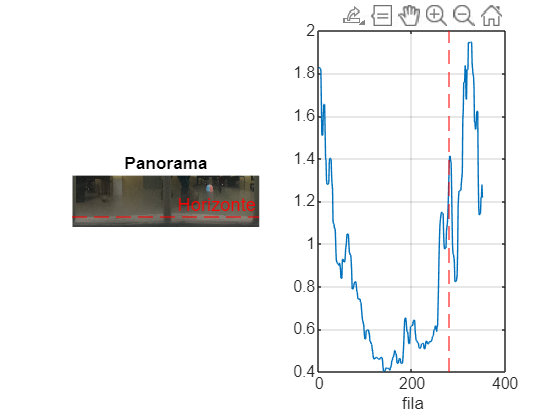

%% ================== HSV + horizonte AUTO + distancia (una imagen) ==================
%% (0) Configuración
panoPath = fullfile('salidas/','img_20250724_145933_pano.png');  
%% ================== MULTI-COLOR HSV + HORIZONTE AUTO + DISTANCIA ==================
thetaOffsetDeg = 0;        % corrimiento azimutal extra (column shift)
doFlip180      = false;    % voltear 180° si lo necesitas (rot90(...,2))

% Altura de cámara: si pones NaN -> devuelve distancia RELATIVA (en alturas)
camHeight_m      = NaN;    % <-- AJUSTA (m); o pon NaN para relativo
alpha_bottom_deg = 80;      % ángulo en la última fila (60–85° suele ir bien)

% ROI vertical: usar sólo la franja inferior (suelo) [0..1]. 0=todo.
bottomFrac = 0.45;

% Limpieza morfológica
minArea   = 500;            % px: área mínima para contar un blob
medfK     = 3;              % mediana
openDisk  = 3;              % disco para imopen

% ====== PALETA DE COLORES (HSV) ======
% Cada color define:
%   name        -> etiqueta
%   hueWindows  -> N×2 con ventanas [lo hi] (maneja wrap 1->0 si lo>hi)
%   satMin,valMin -> mínimos por color (pueden ser bajos para tonos "pastel")
%   maxCount    -> cuántos blobs máximo reportar por color
palette = [
    struct('name','rojo',     'hueWindows',[0.9 1.00; 0.00 0.05], 'satMin',0.30,'valMin',0.15,'maxCount',2)
    struct('name','naranja',  'hueWindows',[0.06 0.15],            'satMin',0.30,'valMin',0.15,'maxCount',2)
    struct('name','amarillo', 'hueWindows',[0.16 0.20],            'satMin',0.25,'valMin',0.20,'maxCount',2)
    struct('name','verde',    'hueWindows',[0.25 0.45],            'satMin',0.25,'valMin',0.15,'maxCount',2)
    struct('name','cian',     'hueWindows',[0.48 0.56],            'satMin',0.25,'valMin',0.15,'maxCount',2)
    struct('name','azul',     'hueWindows',[0.56 0.75],            'satMin',0.25,'valMin',0.15,'maxCount',2)
    struct('name','purpura',  'hueWindows',[0.76 0.83],            'satMin',0.25,'valMin',0.15,'maxCount',2)
    struct('name','magenta',  'hueWindows',[0.82 0.94],            'satMin',0.30,'valMin',0.15,'maxCount',2)
    % Variantes "claras / combinaciones" (pasteles)
    struct('name','rosado',   'hueWindows',[0.90 0.05],            'satMin',0.18,'valMin',0.55,'maxCount',2)
    struct('name','celeste',  'hueWindows',[0.52 0.60],            'satMin',0.18,'valMin',0.55,'maxCount',2)
];

% Colores para dibujar (RGB 0..255) por etiqueta (opcional)
drawColors = containers.Map( ...
    {'rojo','naranja','amarillo','verde','cian','azul','purpura','magenta','rosado','celeste'}, ...
    { [230 60 60], [255 160 60], [240 220 60], [60 200 80], [60 220 220], [70 120 230], [170 90 230], [230 70 200], [255 120 200], [120 200 255] } ...
);

%% (1) Leer/Orientar
I = imread(panoPath);
if doFlip180, I = rot90(I,2); end
if thetaOffsetDeg ~= 0
    I = circshift(I, [0, round((thetaOffsetDeg/360)*size(I,2)), 0]);
end
[R,C,~] = size(I);

%% (2) HSV de la imagen
HSV = rgb2hsv(I);
H = HSV(:,:,1); S = HSV(:,:,2); V = HSV(:,:,3);

%% (3) Horizonte AUTOMÁTICO (energía de gradiente vertical)
Ig  = rgb2gray(I);
Gy  = imfilter(double(Ig), [-1;0;1]/2, 'replicate');
gRow = mean(abs(Gy),2);
gRow = smoothdata(gRow,'movmedian', max(5, round(R*0.01)));
r1 = max(1, round(0.15*R)); r2 = min(R, round(0.85*R));
[~,yy] = max(gRow(r1:r2));  y_h = yy + r1 - 1;          % fila del horizonte

%% (4) Bucle por color: segmentar -> blobs -> métricas
detections = [];    % coleccionaremos filas: [colorId, cx, cy, x y w h, area, azim, width, dist]
overlay = I;

for cidx = 1:numel(palette)
    p = palette(cidx);

    % --- máscara por tonos (maneja wrap si lo>hi)
    M = false(R,C);
    for win = 1:size(p.hueWindows,1)
        lo = p.hueWindows(win,1); hi = p.hueWindows(win,2);
        if lo <= hi
            M = M | (H>=lo & H<=hi);
        else
            M = M | (H>=lo | H<=hi);   % wrap 1->0
        end
    end
    % --- aplicar S y V mínimos (por color)
    M = M & (S >= p.satMin) & (V >= p.valMin);

    % --- restringir a franja inferior (suelo)
    if bottomFrac > 0
        r0 = max(1, round(R*(1-bottomFrac)));
        M(1:r0-1,:) = false;
    end

    % --- limpieza
    if medfK > 1, M = medfilt2(M,[medfK medfK]); end
    if openDisk > 0, M = imopen(M, strel('disk', openDisk)); end
    M = bwareafilt(M, [minArea, inf]);

    if ~any(M(:)), continue; end

    % --- blobs
    CC = bwconncomp(M);
    Sx = regionprops(CC,'Area','BoundingBox','Centroid');
    % ordenar por área descendente
    [~,ord] = sort([Sx.Area], 'descend');
    ord = ord(1:min(numel(ord), p.maxCount));

    % --- procesar top blobs de este color
    for kk = 1:numel(ord)
        s = Sx(ord(kk));
        bb = s.BoundingBox;    % [x y w h]
        ct = s.Centroid;       % [cx cy]
        y_base = bb(2) + bb(4);

        % azimut y ancho angular
        azimuth_deg = (ct(1)-1) * 360 / C;
        width_deg   = (bb(3))   * 360 / C;

        % distancia (absoluta o relativa)
        alpha_obj_deg = -alpha_bottom_deg * ( (y_base - y_h) / max(1,(R - y_h)) );
        alpha_obj_rad = deg2rad(alpha_obj_deg);
        if isnan(camHeight_m)
            dist_val = 1 / tan(abs(alpha_obj_rad));     % relativa
        else
            dist_val = camHeight_m / tan(abs(alpha_obj_rad));  % metros
        end

        % guardar
        detections = [detections; cidx, ct(1), ct(2), bb, s.Area, azimuth_deg, width_deg, dist_val]; %#ok<AGROW>

        % overlay (bbox del color)
        drawColor = [255 255 0];
        if isKey(drawColors, p.name), drawColor = drawColors(p.name); end
        overlay = insertShape(overlay, 'Rectangle', bb, 'Color', drawColor, 'LineWidth', 3);
        lbl = sprintf('%s | \\theta=%.1f° | d=%s', p.name, azimuth_deg, ...
            iff(isnan(camHeight_m), sprintf('%.2f rel', dist_val), sprintf('%.2f m', dist_val)));
        overlay = insertText(overlay, [bb(1) max(1,bb(2)-22)], lbl, 'FontSize', 16, 'BoxOpacity', 0.6);
    end
end

%% (5) Mostrar resultados
figure('Name','Horizonte + energía');
subplot(1,2,1); imshow(I); title('Panorama'); hold on; yline(y_h,'r--','Horizonte');
subplot(1,2,2); plot(gRow); grid on; xline(y_h,'r--'); title('Energía por fila'); xlabel('fila');

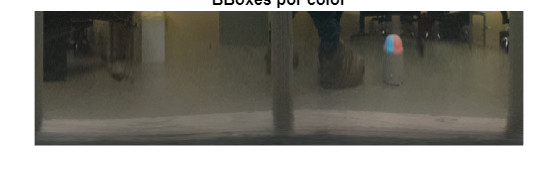


figure('Name','Detecciones multi-color');
imshow(overlay); title('BBoxes por color');


% Imprimir tabla en consola
if ~isempty(detections)
    headers = {'colorId','cx','cy','x','y','w','h','area','azim_deg','width_deg','dist'};
    T = array2table(detections, 'VariableNames', headers);
    % mapear id->nombre
    names = strings(height(T),1);
    for i=1:height(T), names(i) = string(palette(T.colorId(i)).name); end
    T.color = names; T = movevars(T,'color','Before','cx');
    disp(T(:,{'color','cx','cy','x','y','w','h','area','azim_deg','width_deg','dist'}));
else
    warning('No se detectaron colores con la paleta/umbrales actuales.');
end


%% ---- helper inline estilo ternario (para strings sin función aparte) ----
function out = iff(cond, a, b)
if cond, out = a; else, out = b; end
end
